# Data Analysis Flow for BKQD Paper

Wesley Chiang

## Extracting Raw Data

% Prompt for conditions of acquisition
F = uigetdir; %Current file directory
fps = input('Frames rate of acquisition? ');
bits = input('What is the grayscale bit depth? ');
source = convertCharsToStrings(input('QD or TAMRA? ','s'));
start = input('Index to start at? ');
subBG = strcmpi(input('Subtract background? (Y/N) ','s'),'y');

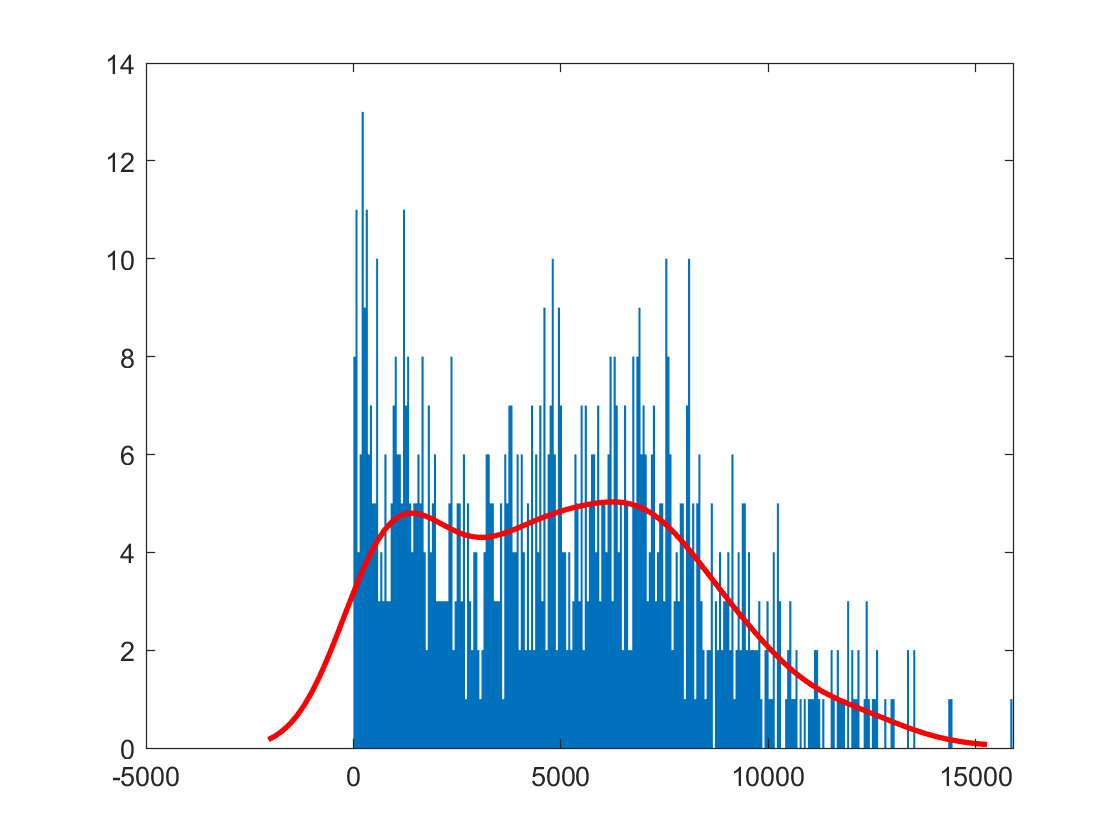

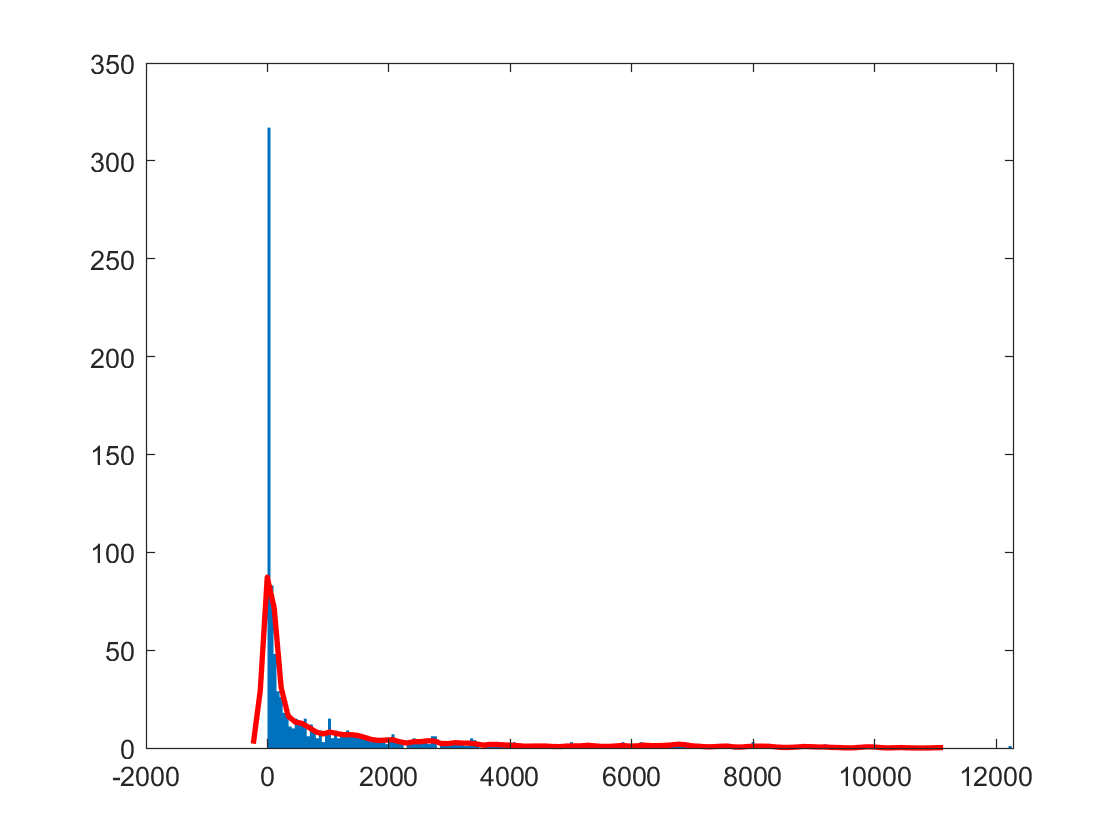

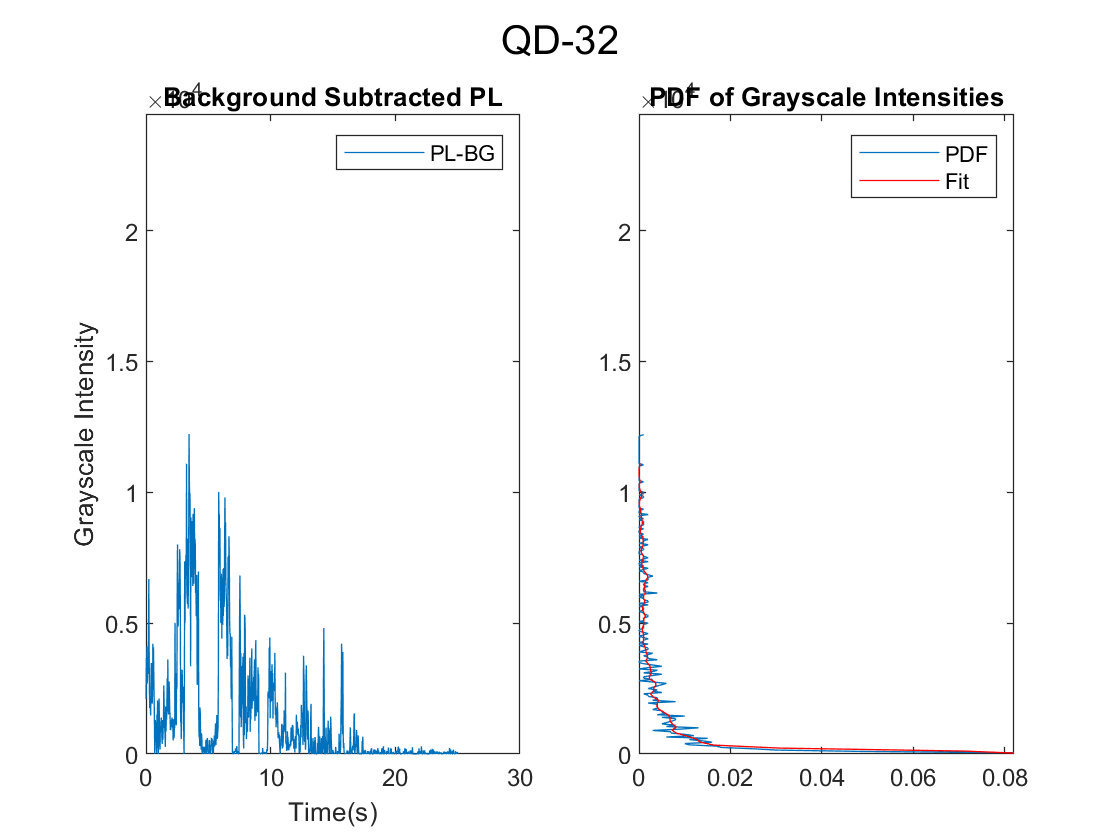

[F_save,BG,PL,cluster,skips]=getData(F,bits,fps,start,source,subBG);

total_clusters = nansum(cluster(:,1));
fprintf("Total # of clusters found = "+total_clusters+"\n");

Total # of clusters found = 19


## Processing Data

Blinks per second, ON Fit Value, ON Fit Error, OFF Fit Value, OFF Fit Error
3.40, -1.30, 0.15, -1.75, 0.18
1.40, -1.22, 0.18, -1.12, 0.14
2.08, -1.51, 0.16, -1.26, 0.23
2.36, -1.10, 0.17, -2.00, 0.25
0.40, -1.00, 0.00, -1.06, 0.16
4.76, -1.73, 0.22, -1.60, 0.20
1.48, -1.28, 0.13, -1.39, 0.19
2.48, -1.35, 0.26, -1.39, 0.22
5.52, -1.84, 0.20, -1.67, 0.23
3.32, -1.52, 0.19, -1.43, 0.18
2.80, -1.17, 0.17, -1.61, 0.28
6.44, -2.01, 0.23, -1.74, 0.25
4.56, -1.64, 0.20, -1.64, 0.24
4.04, -1.58, 0.22, -1.52, 0.14
5.00, -1.84, 0.22, -1.51, 0.30
3.00, -1.52, 0.24, -1.31, 0.22
3.00, -1.53, 0.23, -1.31, 0.22
6.56, -2.00, 0.21, -1.64, 0.36
0.68, -1.00, 0.00, -1.07, 0.11
3.56, -1.55, 0.20, -1.41, 0.23
4.76, -1.87, 0.20, -1.56, 0.25
2.56, -1.46, 0.20, -1.32, 0.22
3.52, -1.20, 0.23, -1.43, 0.20
1.68, -1.19, 0.20, -1.18, 0.17
1.92, -1.18, 0.16, -1.20, 0.26
3.36, -1.54, 0.19, -1.43, 0.22
3.04, -1.41, 0.23, -1.35, 0.22
1.44, -1.44, 0.19, -1.18, 0.24
1.68, -1.07, 0.19, -1.24, 0.19
0.80, -1.15, 0.19, -1.15,

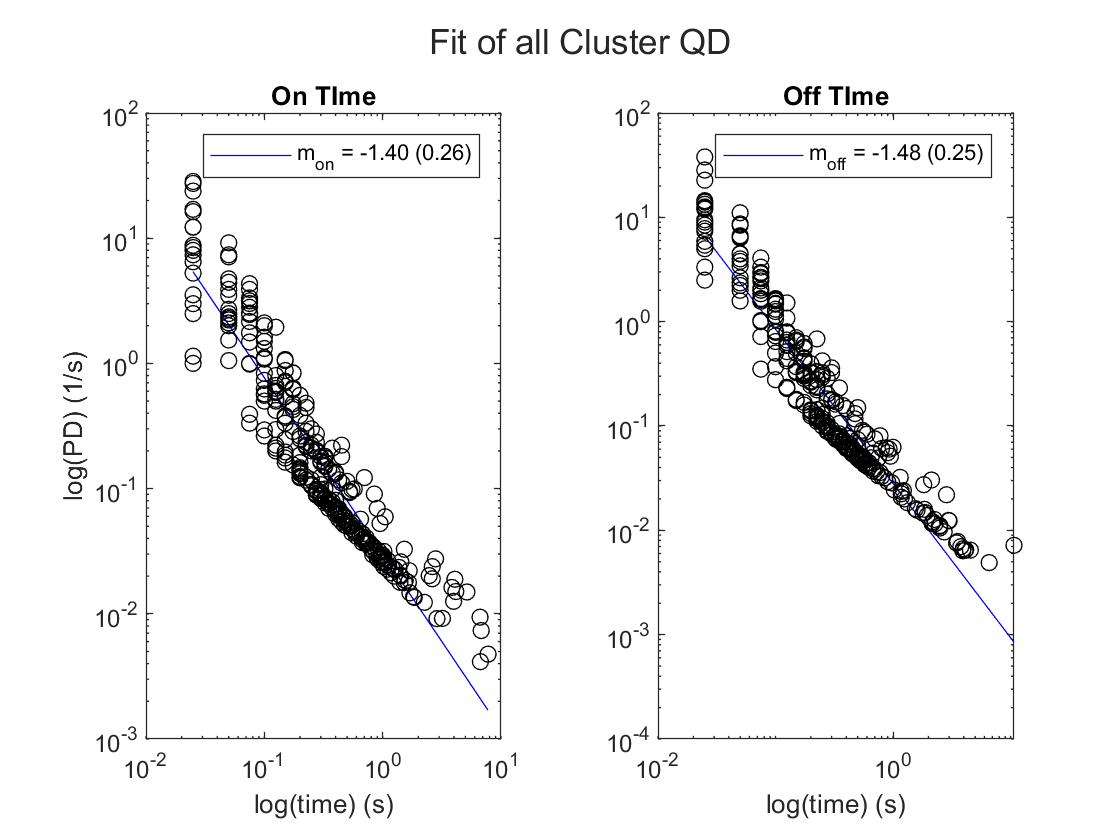

next = strcmpi(input('Do you want to continue? (Y/N) ','s'),'y');
if(next)
    if(subBG)        
        [results,OnTime,OffTime]=blink_cp2(F_save,bits,fps,source,BG,PL,cluster,skips);
        %[results,OnTime,OffTime]=blink_cp3(F_save,bits,fps,source,skips,start)
        F_save = fullfile(F_save, 'Changepoint+Blink');
    else
        [results,OnTime,OffTime]=blink_cp(F_save,bits,fps,source,BG,PL,cluster,skips);
        F_save = fullfile(F_save, 'Regular Blink');
    end
else
    return
end

## Make Histograms

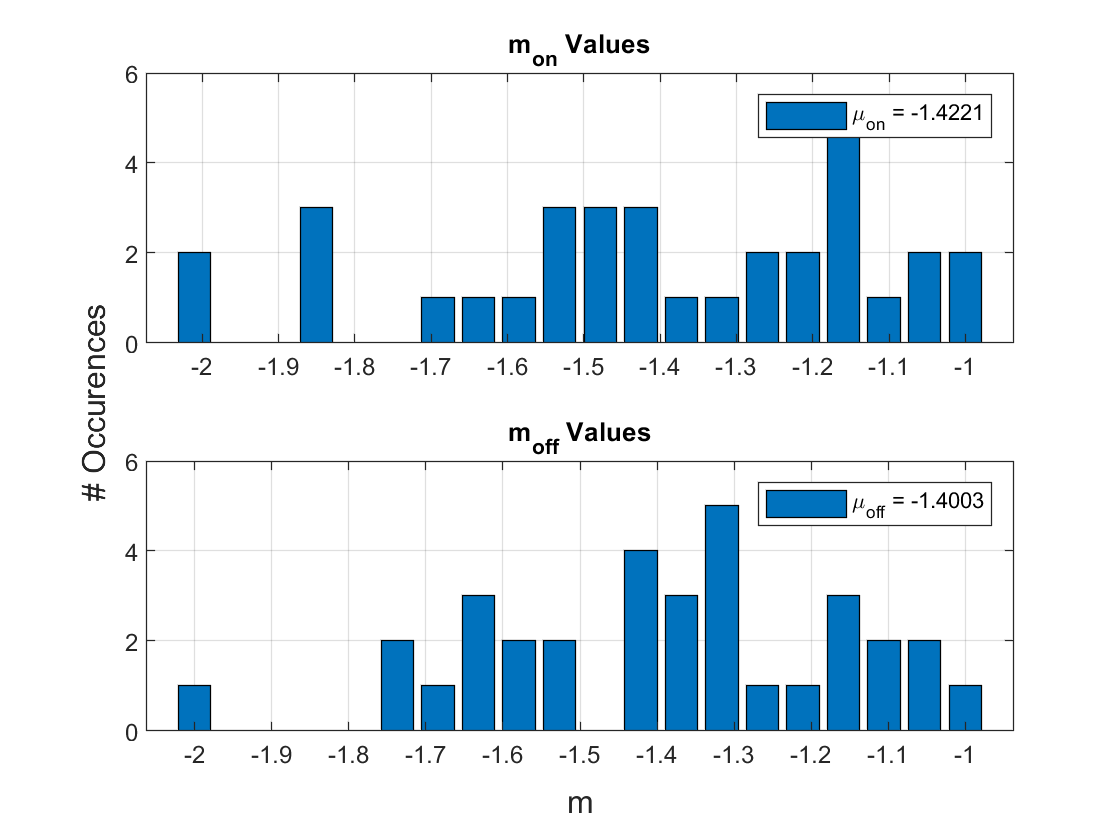

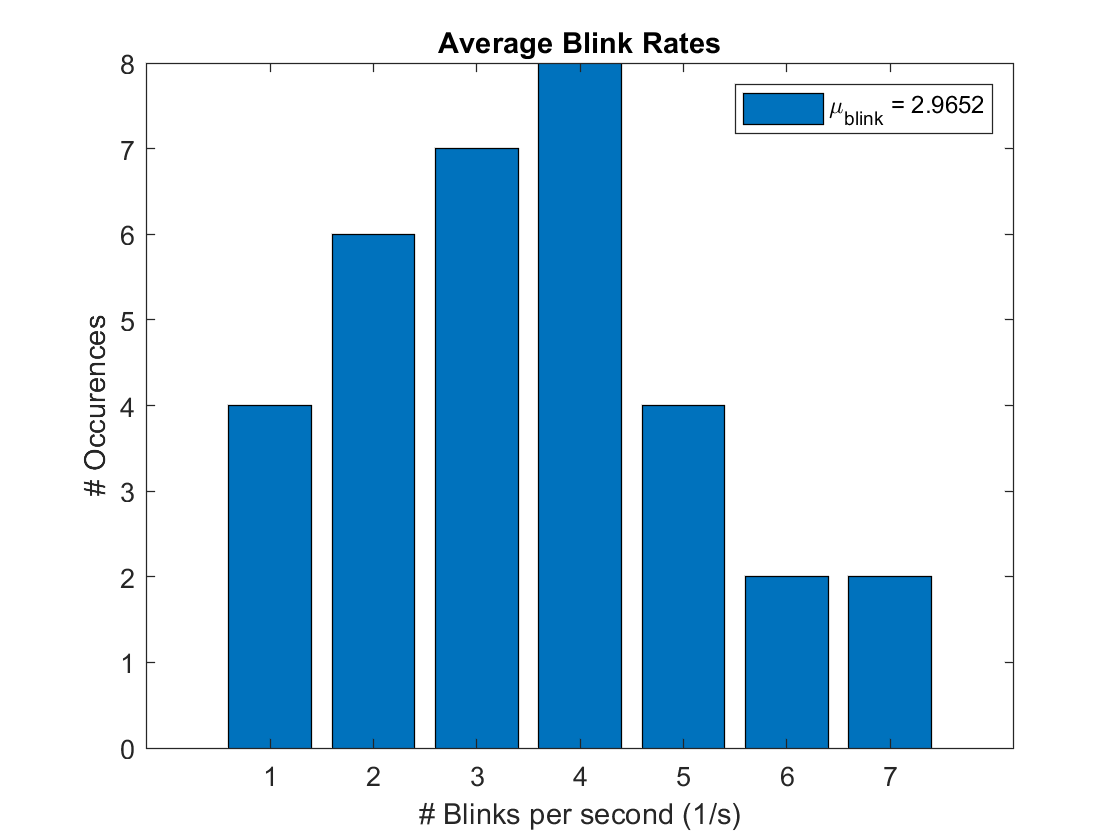

next = strcmpi(input('Do you want to continue? (Y/N) ','s'),'y');
if(next)
    %MakeHistograms;
    MakeFitHistograms;
end

## End

fclose('all')

ans = 0

clear